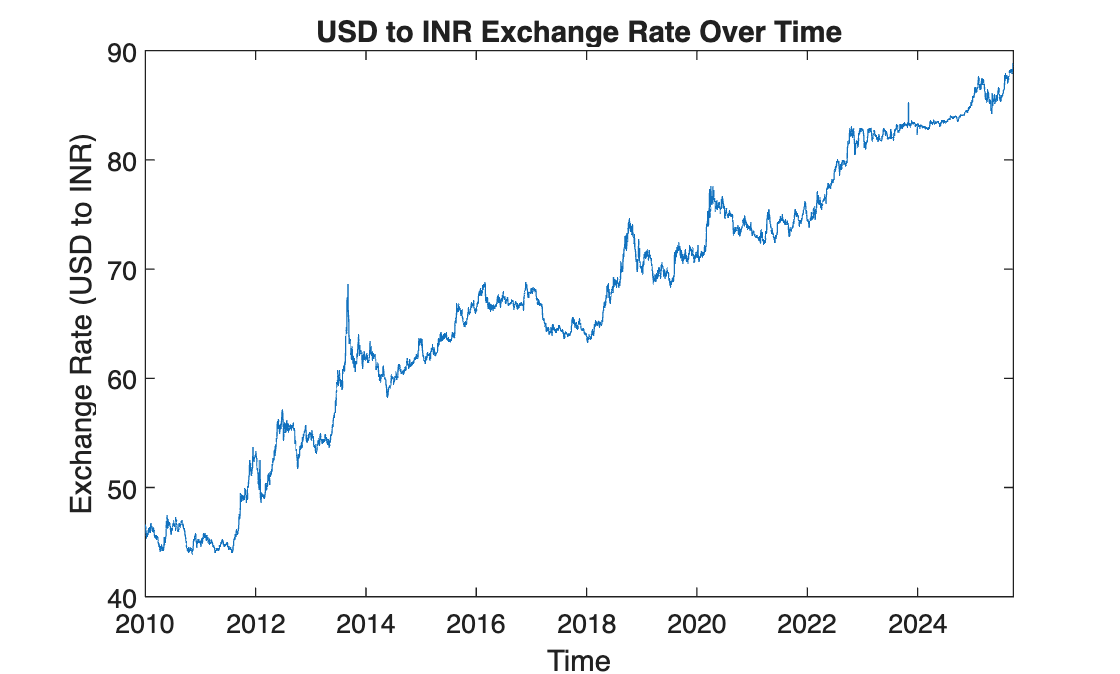

%exchange rate USD/INR 

data= readtable("/Users/selammahmudali/Desktop/UNIMI/YEAR2/Time Series/project/USD_INR.csv");
time = data{:, 1};
exchangeRates = data{:, 2}; % Assuming the second column contains the exchange rates
% Plot the exchange rates over time
figure;
plot(time, exchangeRates);
xlabel('Time');
ylabel('Exchange Rate (USD to INR)');
title('USD to INR Exchange Rate Over Time');

disp(exchangeRates)

       NaN
   46.6100
   46.2880
   46.1200
   45.7200
   45.6880
   45.5180
   45.3580
   45.6180
   45.4880
   45.5630
   45.8030
   45.6380
   45.8480
   46.1180
   46.1080
   46.2230
   46.0780
   45.8480
   46.3180
   46.3480
   46.0980
   46.2880
   46.1000
   45.9000
   46.2100
   46.6200
   46.7100
   46.3900
   46.3780
   46.4000
   46.4000
   46.3380
   45.9800
   46.0080
   46.1400
   46.1800
   46.1000
   46.2680
   46.2880
   46.3000
   45.9000
   46.0000
   46.0280
   45.5500
   45.6700
   45.4500
   45.4000
   45.5500
   45.3100
   45.4500
   45.4980
   45.5580
   45.3900
   45.2800
   45.3900
   45.2500
   45.4700
   45.4000
   45.4000
   45.4880
   45.1100
   44.8000
   44.9400
   44.8000
   44.6000
   44.8080
   44.3600
   44.3400
   44.4000
   44.3400
   44.1200
   44.3400
   44.5780
   44.2100
   44.2900
   44.3180
   44.7280
   44.3900
   44.4000
   44.4400
   44.2900
   44.2500
   44.4500
   44.5000
   44.4500
   44.2500
   44.4000
   44.5500
   44.8500
   45.4600

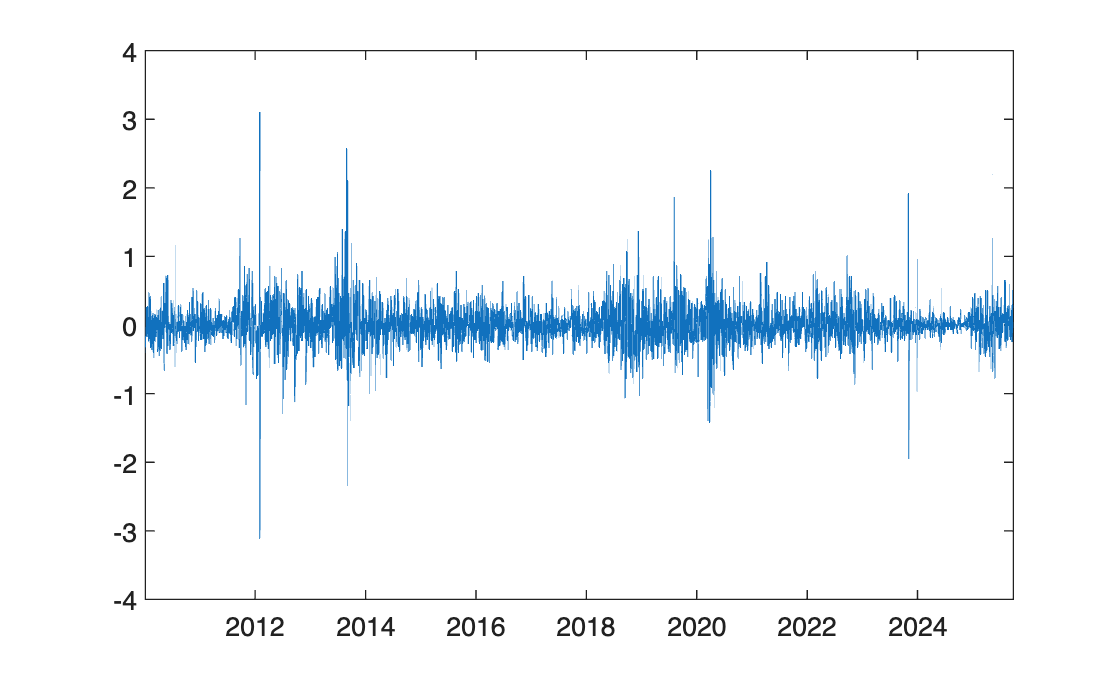

differenced= diff(exchangeRates);
plot(time(2:end), differenced);


%diff = exchangeRates(2:end)-exchangeRates(1:end-1);
%head(diff);
%retruns=diff./exchangeRates(1:end-1) - this is the formula given by the
%price2ret function in 
returns = price2ret(exchangeRates);
head(returns);

       NaN
   -0.0069
   -0.0036
   -0.0087
   -0.0007
   -0.0037
   -0.0035
    0.0057




% Store daily volatility in an array
volatility = zeros(length(exchangeRates)-1, 1); % Preallocate array for daily volatility

for i = 1:length(returns)
    volatility(i) = std(returns(1:i), 'omitnan'); % Store volatility day by day
end

volatility_percentage = volatility .* 100

volatility_percentage =        NaN
         0
    0.2331
    0.2575
    0.3552
    0.3128
    0.2842
    0.4664
    0.4318
    0.4332
    0.4768
    0.4558
    0.4734
    0.4958
    0.4766


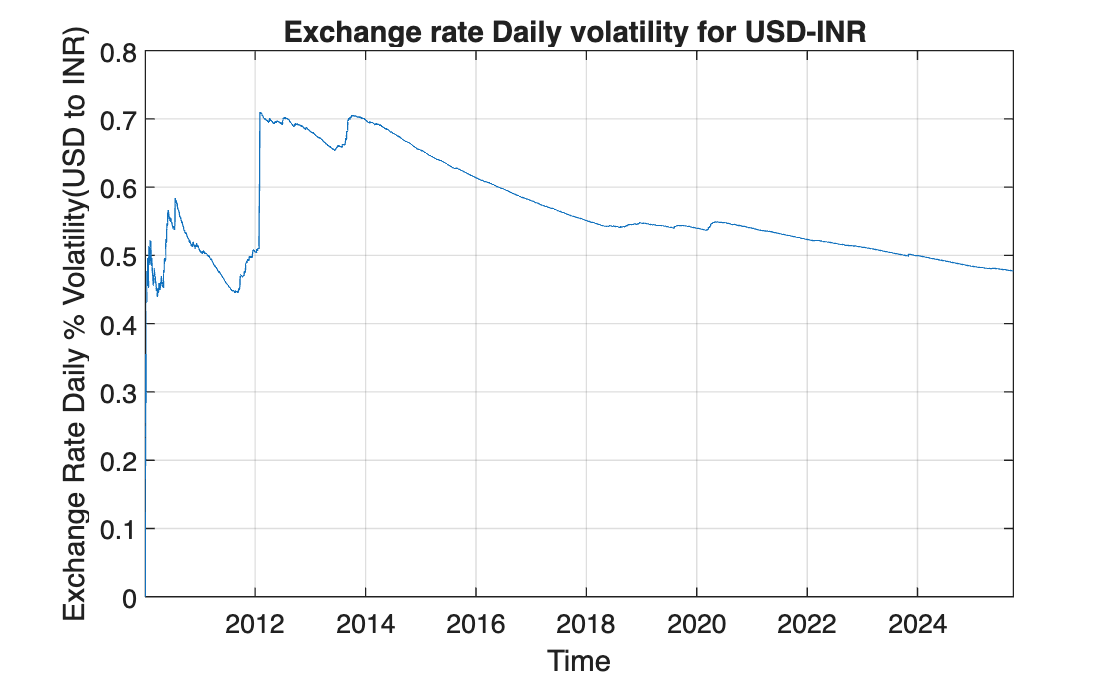


plot(time(2:end), volatility_percentage)
title("Exchange rate Daily volatility for USD-INR ");
ylabel('Exchange Rate Daily % Volatility(USD to INR)');
xlabel("Time");

grid on
hold off

**Early 2010–2012: moderate fluctuations**

- Some short spikes suggest episodes of currency movement or minor market stress.

**2013: sharp jump**

- There’s a clear **spike in volatility** around 2013 — this corresponds to the **“taper tantrum”** period, when the Indian rupee experienced strong depreciation against the USD after U.S. Fed announcements.

- This kind of jump is typical of emerging-market currencies during global uncertainty.

**2014–2018: elevated but slowly declining**

- Volatility stays relatively high (~0.6–0.7%) and gradually declines — consistent with INR stabilizing after structural adjustments and improved capital inflows.

**2019–2025: steady decline**

- A general **downward trend** in volatility, suggesting the USD–INR market became **more stable** — possibly due to:

- Greater foreign exchange reserves by the RBI,

- Managed float interventions, or

- Reduced external shocks.

summary(volatility)


volatility: 4098×1 double

    NumMissing               1  
    Min                      0  
    Median              0.0054  
    Max                 0.0071  
    Mean                0.0056  
    Std             7.1866e-04  

